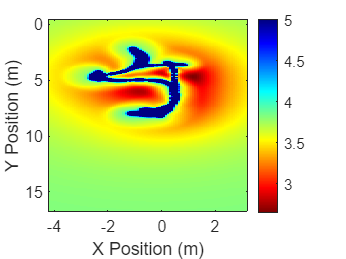

% clc; clear all;
event_data = readmatrix('AllEvents.txt');
pose_data = readmatrix('410_Cs137_Test2.txt');
etime = event_data(:,6);
% ptime = pose_data(:,1);
eenergy = event_data(:,2);
event = event_data(:,1);

% %Parse for x,y
k = 0;
ptime = [];
Xdat = [];
Ydat = [];
skip = 0;
counter = 0;
for i=1:length(pose_data)
    if skip == 1
        skip = 0;
        counter = counter + 1;
        continue
    end
    k = k+1;
    Xdat(i-counter) = pose_data(i,1);
    Ydat(i-counter) = pose_data(i,2);
    skip = 1;
end
k;

%parse for count rate and time
bg_low = 657;
bg_high = 667; %keV
num_events = 0;
delta_t = .75;
step = 1;
rate = [];
t = [];
counter = -1;
index = 1;
for i=1:length(etime)-1
    counter = counter + 1;
    if (eenergy(i) >= bg_low) && (eenergy(i) <= bg_high)
        num_events = num_events + event(i);
    end
    if (etime(i+1) > delta_t*step) | (i==length(etime))
                t(index) = (etime(i)+etime(i-counter))/2;
                rate(index) = num_events/(etime(i)-etime(i-counter));
                index = index + 1;
                step = step + 1;
                num_events = 0;
                counter = 0;
    end
end
interval = k/max(etime);
ptime = linspace(min(etime),k/interval,k);
%interpolate X,Y for equal length vector
X = interp1(ptime,Xdat,t,'linear','extrap');
Y = interp1(ptime,Ydat,t,'linear','extrap');

%Localization
searchdistance = 5; %m
interval = .1; %m
A_det = .057^2;
eps_int = .05;
emis_fac = .944;
act_low = 37*10^3;
act_high = 37*10^4;
act = 0;
countx = 0;
S = 10^20; %arbitrary large number
S_sum_matrix = zeros((ceil((min(X)-searchdistance)+(max(X)+searchdistance)))/interval,ceil(((min(Y)-searchdistance)+(max(Y)+searchdistance))/interval));
    for i=min(X)-3:interval:max(X)+10 %x
        countx = countx + 1;
        county = 0;
        for j=min(Y)-2:interval:max(Y)+3 %y
            county = county + 1;
            S_local = 10^20; %arbitrary large number
            for k=act_low:37*10^3:act_high
                S_sum = 0;
                r = sqrt((X-i).^2+(Y-j).^2);
                eps_geo = A_det./(4*pi*r.^2);
                S_sum = sum((rate - eps_int*eps_geo*emis_fac*k).^2)/sum(rate);
                act_new = k;
                S_sum_matrix(countx,county) = S_local;
                if S_sum < S_local
                    S_local = S_sum;
                    S_sum_matrix(countx,county) = S_local;
                    if S_sum == 0
                        S_local = max(max(S_sum_matrix));
                        S_sum_matrix(countx,county) = S_local;
                    end
                end
                if S_sum < S
                    act = act_new;
                    S = S_sum;
                    xsource = i;
                    ysource = j;
                end  
            end
        end
    end
imagesc([min(Y)-2 max(Y)+1],[min(X) max(X)+10],S_sum_matrix)
colormap(flipud(jet))
colorbar;
caxis([min(min(S_sum_matrix)) 5])
xlabel('X Position (m)')
ylabel('Y Position (m)')

xsource

xsource = 2.5309

ysource

ysource = 2.6160

act

act = 370000

act = act/(37*10^3) % in uCi

act = 10

S

S = 2.6513

% %heatmap
% % m = 1000; n = 1000;
% % xi = linspace(min(X),max(X),m) ; 
% % yi = linspace(min(Y),max(Y),n) ; 
% % [x,y] = meshgrid(xi,yi) ; 
% % z = griddata(X,Y,rate,x,y) ;
% % pcolor(x,y,z) ; shading interp ; colorbar;
% % surf(x,y,z) ; shading interp ; colorbar;
% shift = zeros(length(rate),1);
% for i=1:length(shift)
%     shift(i) = .2*max(rate);
% end
% scatter3(X,Y,shift*0,15,rate)
% colorbar
% hold on
% xlabel('X Position (m)')
% ylabel('Y Position (m)')
% zlabel('Count Rate (#/s)')
% plot(xsource,ysource,'.k','MarkerSize',30)
% hold off
% 